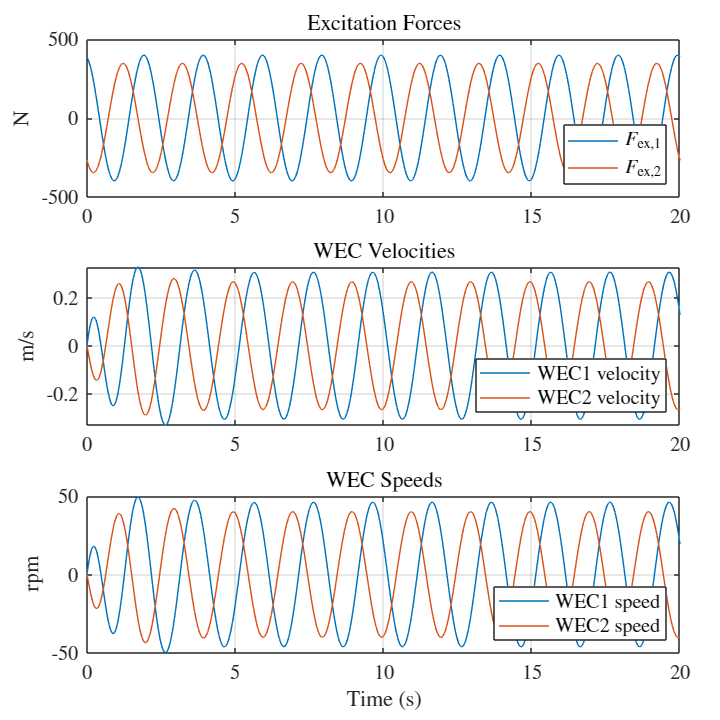

% Plot selected signals from Dataset "LUPA_sim" into three IEEE-style figures
% FIGURE 1 (6x6 in):
%   (1) Fex_1, Fex_2 [N]
%   (2) WEC1_velocity, WEC2_velocity [m/s]
%   (3) WEC1_speed, WEC2_speed [rpm]
%
% FIGURE 2 (6x6 in):
%   (1) WEC1_q_axiscurrent, WEC2_q_axiscurrent [A]
%   (2) WEC1_Ppto, WEC2_PPto [W]
%   (3) WEC1_Psource, WEC2_PSource [W]
%
% FIGURE 3 (6x4 in):
%   (1) (WEC1_Psource + WEC2_Psource) [W]
%   (2) Pdc [W]
%
% Common requirements:
%  - Line width = 0.5 for axes/boxes and curves
%  - Font size = 12
%  - Show only a 20-second window (from start time)
%  - Legends at south-east in all subplots
%  - LaTeX font rendering

% --- Global look: IEEE-ish with LaTeX rendering ---
set(groot, 'DefaultTextInterpreter','latex', ...
           'DefaultLegendInterpreter','latex', ...
           'DefaultAxesTickLabelInterpreter','latex');

fontSize = 12;    % requested font size
lw_curve = 0.5;   % requested curve line width
lw_axes  = 0.5;   % requested axes/box line width

% =========================
% ======== FIGURE 1 =======
% =========================
% --- Grab timeseries for FIGURE 1 ---
Fex1 = LUPA_sim.get('Fex_1').Values;
Fex2 = LUPA_sim.get('Fex_2').Values;

v1   = LUPA_sim.get('WEC1_velocity').Values;
v2   = LUPA_sim.get('WEC2_velocity').Values;

n1   = LUPA_sim.get('WEC1_speed').Values;
n2   = LUPA_sim.get('WEC2_speed').Values;

% Use the time vector from the first signal
t  = Fex1.Time;
t0 = t(1);                 % start time
T  = 20;                   % seconds to display

fig1 = figure('Units','inches','Position',[1 1 6 6], 'Color','w');
tlo1 = tiledlayout(fig1, 3, 1, 'TileSpacing','compact', 'Padding','compact');

% --- Subplot 1: Forces (N)
ax11 = nexttile(tlo1, 1);
plot(t, Fex1.Data, 'LineWidth', lw_curve); hold on;
plot(t, Fex2.Data, 'LineWidth', lw_curve);
grid on; box on;
ylabel('N','FontSize',fontSize);
lg11 = legend({'$F_{\mathrm{ex},1}$', '$F_{\mathrm{ex},2}$'}, ...
              'Location','southeast', 'FontSize',fontSize);
title('Excitation Forces','FontSize',fontSize);

% --- Subplot 2: Velocities (m/s)
ax12 = nexttile(tlo1, 2);
plot(t, v1.Data, 'LineWidth', lw_curve); hold on;
plot(t, v2.Data, 'LineWidth', lw_curve);
grid on; box on;
ylabel('m/s','FontSize',fontSize);
lg12 = legend({'WEC1 velocity','WEC2 velocity'}, ...
              'Location','southeast', 'FontSize',fontSize);
title('WEC Velocities','FontSize',fontSize);

% --- Subplot 3: Speeds (rpm)
ax13 = nexttile(tlo1, 3);
plot(t, n1.Data, 'LineWidth', lw_curve); hold on;
plot(t, n2.Data, 'LineWidth', lw_curve);
grid on; box on;
ylabel('rpm','FontSize',fontSize);
xlabel('Time (s)','FontSize',fontSize);
lg13 = legend({'WEC1 speed','WEC2 speed'}, ...
              'Location','southeast', 'FontSize',fontSize);
title('WEC Speeds','FontSize',fontSize);

% --- Style: axes & legend boxes
set([ax11 ax12 ax13], 'FontSize', fontSize, 'LineWidth', lw_axes);
set(lg11, 'Box','on', 'LineWidth', lw_axes);
set(lg12, 'Box','on', 'LineWidth', lw_axes);
set(lg13, 'Box','on', 'LineWidth', lw_axes);

% --- Show only first 20 seconds
linkaxes([ax11 ax12 ax13], 'x');
xlim(ax11, [t0, t0+T]);

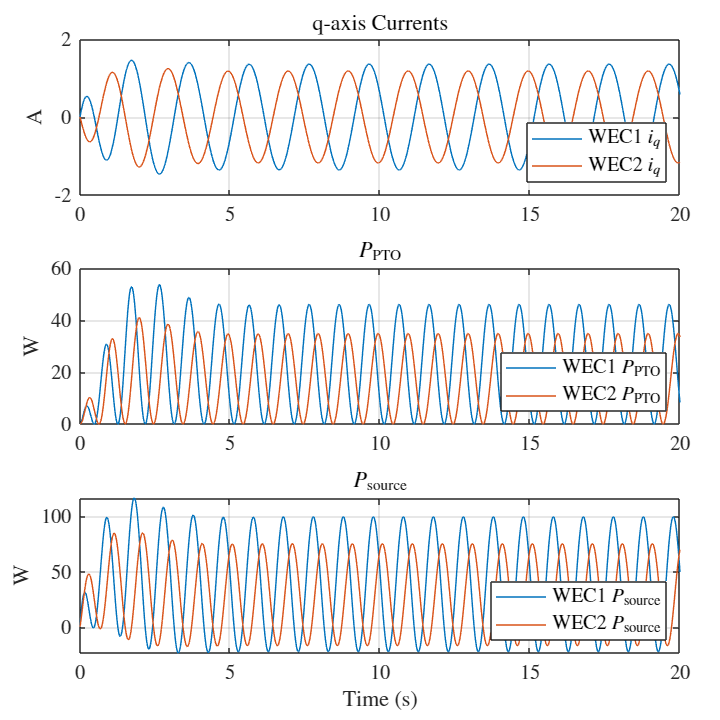


% =========================
% ======== FIGURE 2 =======
% =========================
% Robustly fetch potentially variably-cased elements:
q1_ts   = get_ts_ci(LUPA_sim, {'WEC1_q_axiscurrent','WEC1\_q\_axiscurrent','WEC1\_q\_axis\_current','WEC1_iq','iq1'});
q2_ts   = get_ts_ci(LUPA_sim, {'WEC2_q_axiscurrent','WEC2\_q\_axiscurrent','WEC2\_q\_axis\_current','WEC2_iq','iq2'});

Ppto1   = get_ts_ci(LUPA_sim, {'WEC1_Ppto','WEC1_PPto','WEC1\_Ppto','WEC1\_PPto','Ppto1'});
Ppto2   = get_ts_ci(LUPA_sim, {'WEC2_Ppto','WEC2_PPto','WEC2\_Ppto','WEC2\_PPto','Ppto2'});

Psrc1   = get_ts_ci(LUPA_sim, {'WEC1_Psource','WEC1_PSource','WEC1\_Psource','WEC1\_PSource','Psource1'});
Psrc2   = get_ts_ci(LUPA_sim, {'WEC2_Psource','WEC2_PSource','WEC2\_Psource','WEC2\_PSource','Psource2'});

fig2 = figure('Units','inches','Position',[1 1 6 6], 'Color','w');
tlo2 = tiledlayout(fig2, 3, 1, 'TileSpacing','compact', 'Padding','compact');

% --- Subplot 1: q-axis currents (A)
ax21 = nexttile(tlo2, 1);
plot(q1_ts.Time, q1_ts.Data, 'LineWidth', lw_curve); hold on;
plot(q2_ts.Time, q2_ts.Data, 'LineWidth', lw_curve);
grid on; box on;
ylabel('A','FontSize',fontSize);
lg21 = legend({'WEC1 $i_q$','WEC2 $i_q$'}, ...
              'Location','southeast', 'FontSize',fontSize);
title('q-axis Currents','FontSize',fontSize);

% --- Subplot 2: P_{PTO} (W)
ax22 = nexttile(tlo2, 2);
plot(Ppto1.Time, Ppto1.Data, 'LineWidth', lw_curve); hold on;
plot(Ppto2.Time, Ppto2.Data, 'LineWidth', lw_curve);
grid on; box on;
ylabel('W','FontSize',fontSize);
lg22 = legend({'WEC1 $P_{\mathrm{PTO}}$','WEC2 $P_{\mathrm{PTO}}$'}, ...
              'Location','southeast', 'FontSize',fontSize);
title('$P_{\mathrm{PTO}}$','FontSize',fontSize);

% --- Subplot 3: P_{source} (W)
ax23 = nexttile(tlo2, 3);
plot(Psrc1.Time, Psrc1.Data, 'LineWidth', lw_curve); hold on;
plot(Psrc2.Time, Psrc2.Data, 'LineWidth', lw_curve);
grid on; box on;
ylabel('W','FontSize',fontSize);
xlabel('Time (s)','FontSize',fontSize);
lg23 = legend({'WEC1 $P_{\mathrm{source}}$','WEC2 $P_{\mathrm{source}}$'}, ...
              'Location','southeast', 'FontSize',fontSize);
title('$P_{\mathrm{source}}$','FontSize',fontSize);

% --- Style: axes & legend boxes
set([ax21 ax22 ax23], 'FontSize', fontSize, 'LineWidth', lw_axes);
set(lg21, 'Box','on', 'LineWidth', lw_axes);
set(lg22, 'Box','on', 'LineWidth', lw_axes);
set(lg23, 'Box','on', 'LineWidth', lw_axes);

% --- Show only the first 20 seconds on FIGURE 2 as well
linkaxes([ax21 ax22 ax23], 'x');
xlim(ax21, [t0, t0+T]);

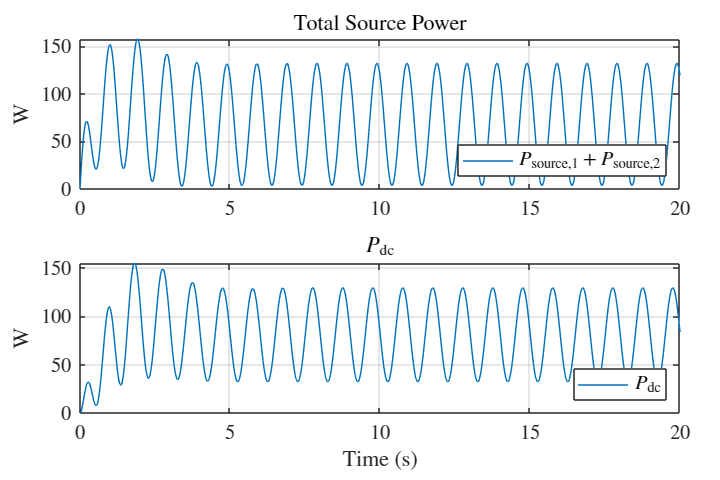


% =========================
% ======== FIGURE 3 =======
% =========================
% Fetch again (already available above): Psrc1, Psrc2
% Also fetch Pdc (case-insensitive candidates)
Pdc_ts = get_ts_ci(LUPA_sim, {'Pdc','PDC','P\_dc','P\_DC','Pdc\_bus','P\_bus'});

% Compute sum of source powers with time alignment
tSum = Psrc1.Time;
sumSrc = Psrc1.Data;
if isequal(size(Psrc2.Time), size(tSum)) && all(Psrc2.Time == tSum)
    sumSrc = sumSrc + Psrc2.Data;
else
    % interpolate Psrc2 onto Psrc1's time base
    sumSrc = sumSrc + interp1(Psrc2.Time, Psrc2.Data, tSum, 'linear', 'extrap');
end

fig3 = figure('Units','inches','Position',[1 1 6 4], 'Color','w');
tlo3 = tiledlayout(fig3, 2, 1, 'TileSpacing','compact', 'Padding','compact');

% --- Subplot 1: Sum of Psource (W)
ax31 = nexttile(tlo3, 1);
plot(tSum, sumSrc, 'LineWidth', lw_curve); hold on;
grid on; box on;
ylabel('W','FontSize',fontSize);
lg31 = legend({'$P_{\mathrm{source,1}} + P_{\mathrm{source,2}}$'}, ...
              'Location','southeast', 'FontSize',fontSize);
title('Total Source Power','FontSize',fontSize);

% --- Subplot 2: Pdc (W)
ax32 = nexttile(tlo3, 2);
plot(Pdc_ts.Time, Pdc_ts.Data, 'LineWidth', lw_curve); hold on;
grid on; box on;
ylabel('W','FontSize',fontSize);
xlabel('Time (s)','FontSize',fontSize);
lg32 = legend({'$P_{\mathrm{dc}}$'}, 'Location','southeast', 'FontSize',fontSize);
title('$P_{\mathrm{dc}}$','FontSize',fontSize);

% --- Style: axes & legend boxes
set([ax31 ax32], 'FontSize', fontSize, 'LineWidth', lw_axes);
set(lg31, 'Box','on', 'LineWidth', lw_axes);
set(lg32, 'Box','on', 'LineWidth', lw_axes);

% --- Show only the first 20 seconds on FIGURE 3
linkaxes([ax31 ax32], 'x');
xlim(ax31, [t0, t0+T]);


% =========================
% ===== Helper (local) =====
% =========================
function ts = get_ts_ci(ds, nameCandidates)
%GET_TS_CI Case-insensitive fetch of a timeseries from a Dataset.
%   ts = GET_TS_CI(ds, {'NameA','NameB',...})
%   Tries each candidate (case-insensitive) against ds element names.
%   Throws an error with a short listing if none found.
    if ischar(nameCandidates) || isstring(nameCandidates)
        nameCandidates = {char(nameCandidates)};
    end
    % Collect dataset element names
    N = ds.getLength;
    names = cell(1,N);
    for k = 1:N
        names{k} = ds.getElement(k).Name;
    end
    % Try candidates
    idx = [];
    for c = 1:numel(nameCandidates)
        nm = strrep(char(nameCandidates{c}), '\_', '_'); % tolerate escaped underscores
        idx = find(strcmpi(nm, names), 1, 'first');
        if ~isempty(idx), break; end
    end
    if isempty(idx)
        shortList = strjoin(names(1:min(N,8)), ', ');
        error('Signal not found. Tried: %s. Available (first few): %s', ...
              strjoin(nameCandidates, ', '), shortList);
    end
    ts = ds.getElement(idx).Values;
end
